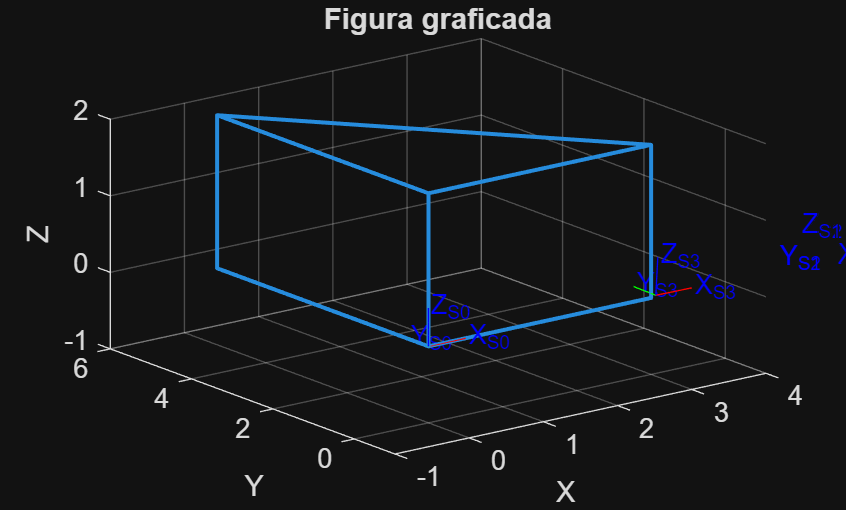

clear all
clc
% Inicialización del entorno de trabajo eliminando variables previas y limpiando consola.

% Definición de las matrices de transformación homogénea utilizando la Toolbox de Robótica de Peter Corke.
% Cada matriz representa una articulación o cambio de marco en el sistema.

H0 = SE3();                             % Matriz identidad que define el sistema de referencia base.
H1 = SE3(rotz(pi), [5 0 0]);            % Rotación de 180° sobre Z seguida de una traslación de 5 unidades en X.
H2 = SE3(roty(pi/2), [0 0 0]);          % Rotación de 90° sobre el eje Y, sin traslación adicional.
H3 = SE3(rotx(150*pi/180), [-2 0 0]);   % Rotación de 150° sobre X y traslación de -2 unidades en X.

% Composición de transformaciones acumuladas desde el marco base hasta el marco final.
H0_1 = H0 * H1;
H1_2 = H0_1 * H2;
H2_3 = H1_2 * H3;  % Matriz de transformación homogénea global del marco 3 respecto al marco base.

% Definición de los puntos de la estructura para representar una figura tridimensional.
x = [0 3 3 0 0 0     0     0 0     3];
y = [0 0 0 0 0 5.196 5.196 0 5.196 0];
z = [0 0 2 2 0 0     2     2 2     2];

% Gráfica tridimensional de la estructura basada en los puntos definidos.
plot3(x, y, z, 'LineWidth', 1.5);
axis([-1 4 -1 6 -1 2]); grid on;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Figura graficada');
hold on;

% Visualización de los marcos de coordenadas utilizando trplot para mostrar orientación espacial.
trplot(H0,    'rgb', 'frame', 'S0', 'axis', [-1 4 -1 6 -0.5 2], 'length', 0.5);
trplot(H0_1,  'rgb', 'frame', 'S1', 'length', 0.5);
trplot(H1_2,  'rgb', 'frame', 'S2', 'length', 0.5);
trplot(H2_3,  'rgb', 'frame', 'S3', 'length', 0.5);
hold off;


% Se muestra por consola la transformación homogénea final que describe la posición y orientación del marco 3 respecto al marco base.
disp('Transformación H2_3:');

Transformación H2_3:


disp(H2_3);

      0.9981   -0.0535   0.02985     3.004
     0.05478    0.9975  -0.04411   -0.1096
    -0.02741   0.04566    0.9986   0.05482
           0         0         0         1
